# **Generalized chi-square distribution** · Getting started

The generalized chi-square variable is a quadratic form of a normal variable, or equivalently, a linear sum of independent non-central chi-square variables and a normal variable.

For more features and documentation, type:

doc gx2stat
doc gx2rnd
doc gx2cdf
doc gx2cdf_davies
doc gx2cdf_imhof
doc gx2cdf_ruben
doc gx2pdf
doc gx2inv
doc gx2_params_norm_quad 

If you use this toolbox, please cite: [A method to integrate and classify normal distributions](https://arxiv.org/abs/2012.14331).

Bugs/questions/comments to abhranil.das@utexas.edu.

Abhranil Das, Center for Perceptual Systems, University of Texas at Austin

## Calculate mean and variance

% gx2 parameters
lambda=[1 -10 2];
m=[1 2 3];
delta=[2 3 7];
sigma=5;
c=10;

[mu,v]=gx2stat(lambda,m,delta,sigma,c)

mu =    -17


v =         1771


## Generate random samples

r=gx2rnd(lambda,m,delta,sigma,c,[1 1e4]);

## Calculate pdf and cdf

x=[10 25];
f=gx2pdf(x,lambda,m,delta,sigma,c)

f =    0.012056453965248   0.008797713715788


p=gx2cdf(x,lambda,m,delta,sigma,c,'AbsTol',0,'RelTol',1e-4)

p =    0.714979825290199   0.878998656311740


### Plot pdf and sample histogram

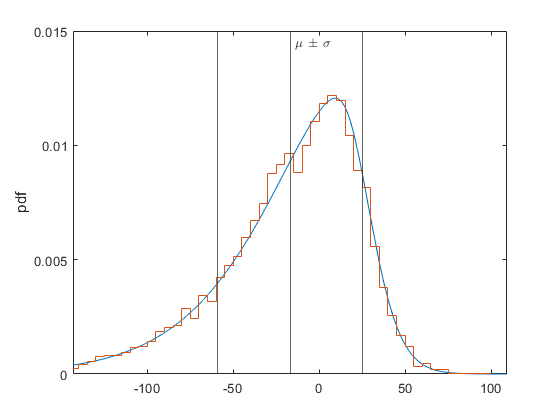

fplot(@(x) gx2pdf(x,lambda,m,delta,sigma,c))
hold on; histogram(r,'normalization','pdf','displaystyle','stairs')
xline(mu,'-',{'\mu \pm \sigma'},'labelorientation','horizontal');
xline(mu-sqrt(v),'-'); xline(mu+sqrt(v),'-');
xlim([mu-3*sqrt(v),mu+3*sqrt(v)]); ylim([0 .015]); ylabel 'pdf'

### Plot cdf

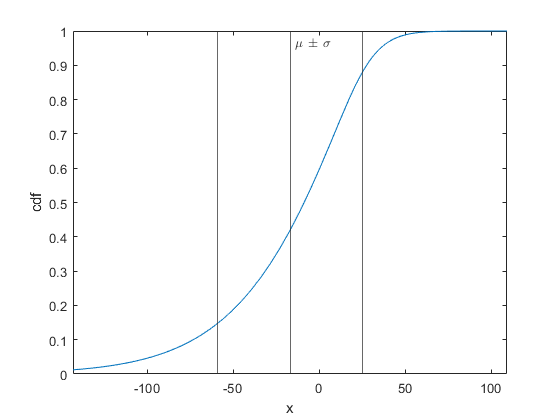

figure; fplot(@(x) gx2cdf(x,lambda,m,delta,sigma,c));
xline(mu,'-',{'\mu \pm \sigma'},'labelorientation','horizontal');
xline(mu-sqrt(v),'-'); xline(mu+sqrt(v),'-');
xlim([mu-3*sqrt(v),mu+3*sqrt(v)]); ylim([0 1]); xlabel x; ylabel 'cdf'

## Calculate inverse cdf

x=gx2inv([0.5 0.9],lambda,m,delta,sigma,c)

x =   -8.765662415017413  27.532048762926728


## Distribution of quadratic form of a normal variable

Normal parameters:

mu=[5;6]; % mean
v=[2 1; 1 3]; % covariance matrix

$q(\mathbf{x})=(x_1+x_2)^2-x_1-1$` = [x1;x2]'*[1 1; 1 1]*[x1;x2] + [-1;0]'*[x1;x2] -1`

quad.q2=[1 1; 1 1];
quad.q1=[-1;0];
quad.q0=-1;

Sample normal random vectors:

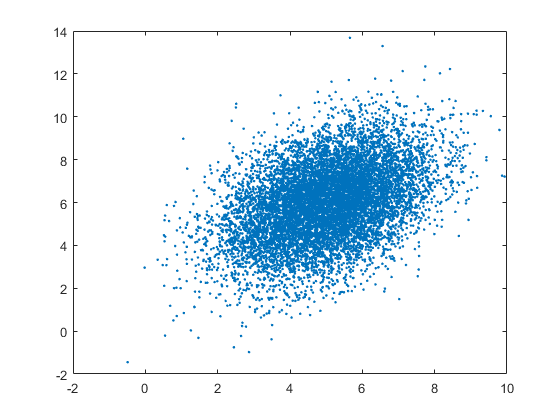

x=mvnrnd(mu,v,1e4)';
plot(x(1,:),x(2,:),'.')

Compute the quadratic form *q*:

q=dot(x,quad.q2*x)+quad.q1'*x+quad.q0;

Get generalized chi-square parameters corresponding to this quadratic form:

[lambda,m,delta,sigma,c]=gx2_params_norm_quad(mu,v,quad)

lambda =    6.999999999999996


m =      1


delta =   16.618804664723040


sigma =    0.845154254728509


c =   -1.331632653061220


Compare the sampled and calculated distributions of *q*:

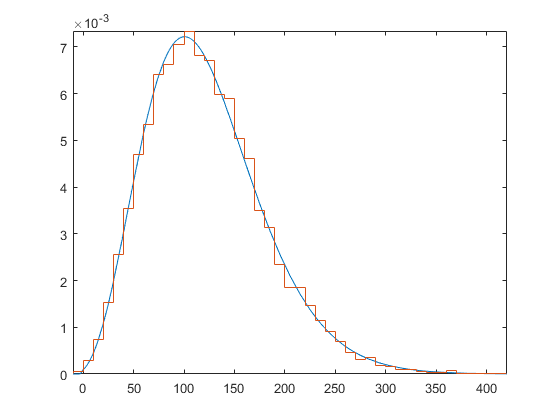

fplot(@(x) gx2pdf(x,lambda,m,delta,sigma,c)); hold on
histogram(q,'normalization','pdf','displaystyle','stairs')

Compare the sampled and calculated means and variances:

[mu_q,v_q]=gx2stat(lambda,m,delta,sigma,c);
[mu_q mean(q)]

ans = 	1.0e+02 *

   1.220000000000000   1.220014880163810


[v_q var(q)]

ans = 	1.0e+03 *

   3.355999999999998   3.330106727151422


Compare the sampled and calculated probabilities $p(q(\mathbf{x})<50)$:

mean(q<50)

ans =    0.087000000000000


gx2cdf(50,lambda,m,delta,sigma,c)

ans =    0.085593326995655
